# Behavioural model equilibrium and stability analysis

Initialization 

obj = functionsContainer;
x = linspace(0,1,1000);
fig = 0;

There are several different equilibrium possible, based on the parameters reciprocal relations. In the following sections are presented and their stability is also verified. 

## Caso R1 <1 and R2 < 1

% Simulation parameters
R1 = 0.89;
R2 = 0.65;
k1 =  1/7; %from Ca to Co
k2 = 1/2; %from C to Ag
lambda_1 = k1/R1; %fatigue to mantain Co behaviour
lambda_2 = k2/R2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this condition. 

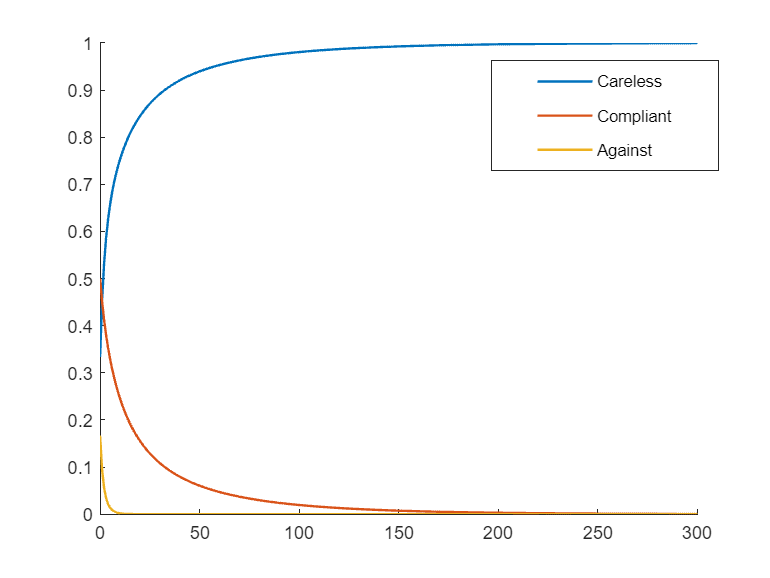

time = 300;
Co_zero = 30e6;
Ag_zero = 10e6;
[taxisRK,xaxisRK,yaxisRK,zaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,Co_zero, Ag_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,xaxisRK, 'linewidth',1.3 )
plot(taxisRK,yaxisRK, 'linewidth',1.3 )
plot(taxisRK,zaxisRK, 'linewidth',1.3 )
legend('Careless', 'Compliant', 'Against')

legend("Position", [0.70777,0.8488,0.18929,0.11905])
hold off

legend("Position", [0.6392,0.70549,0.29328,0.18997])

Plot of the nullclines

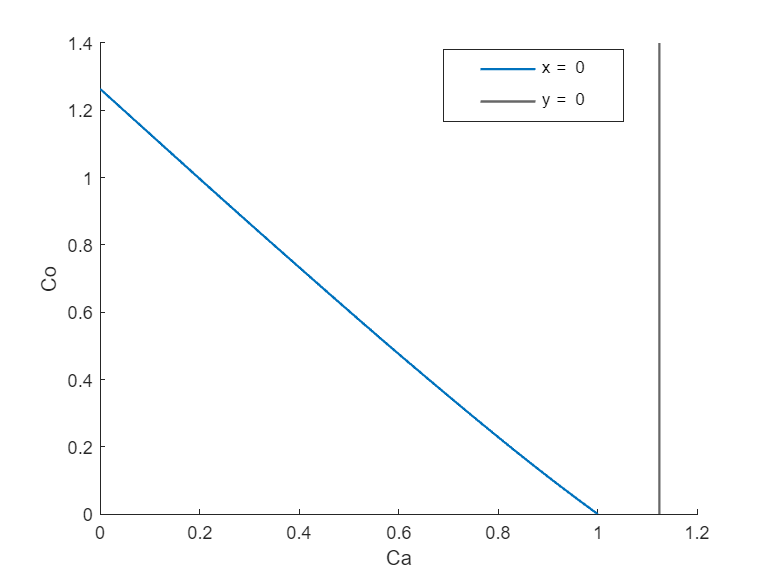

fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
xlabel("Ca")
ylabel("Co")
legend('x^ = 0', 'y^ = 0')
hold off

xlim("auto")
ylim("auto")
legend("Position", [0.57634,0.79099,0.23349,0.12348])

Definition of system equation and Jacobian calculation

syms Ca Co Ag

eq_Ca = -k1*Ca*Co - k2*(1-Ca-Co)*Ca + lambda_1*Co + lambda_2 * (1-Ca-Co);
eq_Co = +k1*Ca*Co - lambda_1*Co;

% The Jacobiana of this equation in this case is:
Jac(Ca, Co) = jacobian([eq_Ca, eq_Co], [Ca, Co])

$$Jac(Ca, Co) = \left(\begin{array}{cc} \mathrm{Ca}+\frac{5\,\mathrm{Co}}{14}-\frac{33}{26} & \frac{5\,\mathrm{Ca}}{14}-\frac{4930}{8099}\\ \frac{\mathrm{Co}}{7} & \frac{\mathrm{Ca}}{7}-\frac{100}{623} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(Ca,Co) = trace(Jac(Ca,Co))

$$Trac(Ca, Co) = \frac{8\,\mathrm{Ca}}{7}+\frac{5\,\mathrm{Co}}{14}-\frac{23159}{16198}$$

% Determinant
d(Ca,Co) = det(Jac)

$$d(Ca, Co) = \frac{{\mathrm{Ca}}^{2}}{7}-\frac{791\,\mathrm{Ca}}{2314}+\frac{240\,\mathrm{Co}}{8099}+\frac{1650}{8099}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this case the value of equilibrium correspond to Ca = 1 and Co =0.

value1 = 1;
value2 =  0;
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{4647}{16198}$$


det_J =  d(value1, value2)

$$det\_J = \frac{11}{2314}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

## Caso R1 > R2 and R1 > 1

% Simulation parameters
R1 = 1.5;
R2 = 1.2;
k1 =  1/2.05; %from Ca to Co
k2 = 1/2; %from C to Ag
lambda_1 = k1/R1; %fatigue to mantain Co behaviour
lambda_2 = k2/R2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this condition. 

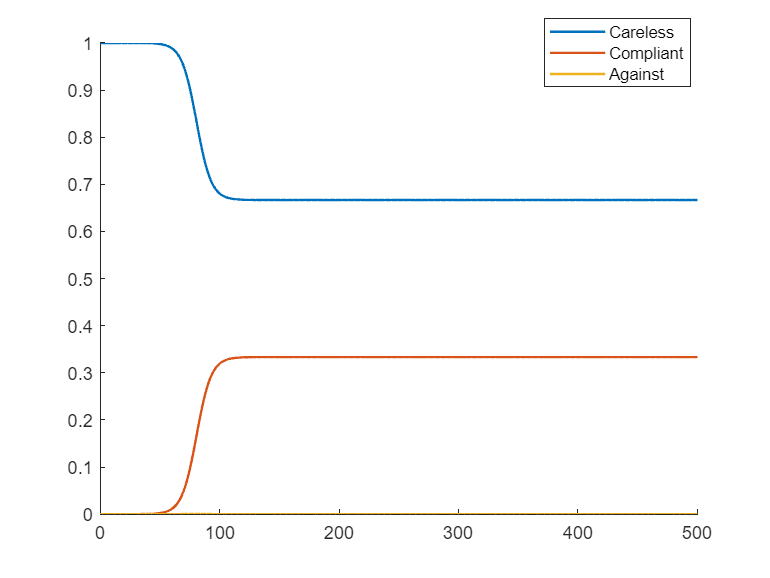

time = 500;
Co_zero = 40;
Ag_zero = 40;
[taxisRK,xaxisRK,yaxisRK,zaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,Co_zero, Ag_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,xaxisRK, 'linewidth',1.3 )
plot(taxisRK,yaxisRK, 'linewidth',1.3 )
plot(taxisRK,zaxisRK, 'linewidth',1.3 )
legend('Careless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
legend("Position", [0.70777,0.8488,0.18929,0.11905])
hold off

Plot of the nullclines

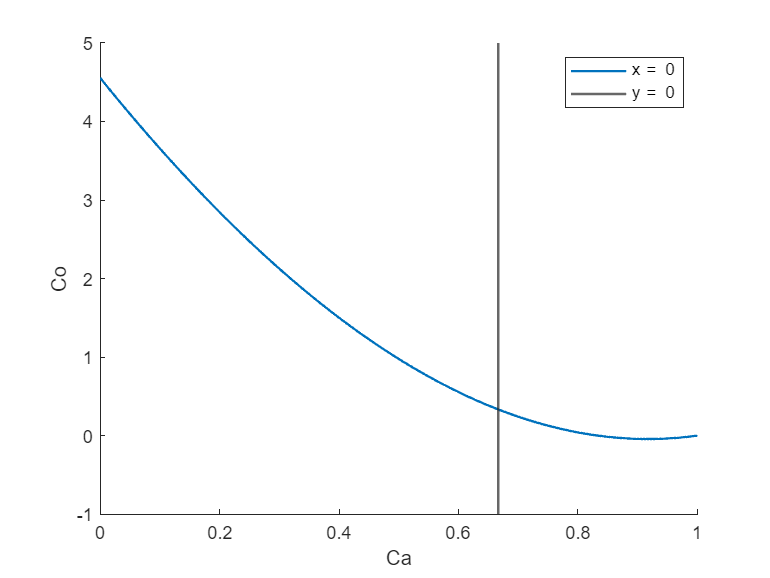

fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
xlabel("Ca")
ylabel("Co")
legend('x^ = 0', 'y^ = 0')
hold off

Definition of system equation and Jacobian calculation

syms Ca Co Ag

eq_Ca = -k1*Ca*Co - k2*(1-Ca-Co)*Ca + lambda_1*Co + lambda_2 * (1-Ca-Co);
eq_Co = +k1*Ca*Co - lambda_1*Co;

% The Jacobiana of this equation in this case is:
Jac(Ca, Co) = jacobian([eq_Ca, eq_Co], [Ca, Co])

$$Jac(Ca, Co) = \left(\begin{array}{cc} \mathrm{Ca}+\frac{\mathrm{Co}}{82}-\frac{11}{12} & \frac{\mathrm{Ca}}{82}-\frac{15}{164}\\ \frac{20\,\mathrm{Co}}{41} & \frac{20\,\mathrm{Ca}}{41}-\frac{40}{123} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(Ca,Co) = trace(Jac(Ca,Co))

$$Trac(Ca, Co) = \frac{61\,\mathrm{Ca}}{41}+\frac{\mathrm{Co}}{82}-\frac{611}{492}$$

% Determinant
d(Ca,Co) = det(Jac)

$$d(Ca, Co) = \frac{20\,{\mathrm{Ca}}^{2}}{41}-\frac{95\,\mathrm{Ca}}{123}+\frac{5\,\mathrm{Co}}{123}+\frac{110}{369}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

The value at equilibrium in this case can be found using the formula Ca = $\lambda_1 / k1$ and Co = 1-$\lambda_1 / k1$   

value1 = lambda_1/k1; 
value2 =  (1-lambda_1/k1);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{121}{492}$$

det_J =  d(value1, value2)

$$det\_J = \frac{5}{369}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

## Caso R1 = R2

% Simulation parameters
R1 = 1.2;
R2 = 1.2;
k1 =  1/2.05; %from Ca to Co
k2 = 1/2; %from C to Ag
lambda_1 = k1/R1; %fatigue to mantain Co behaviour
lambda_2 = k2/R2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this condition. In this case there is an equilibrium visible from the evolution of the system, but its value cannot  be directly calculated with the method used before. In fact the initial conidtions have an impact on the final value reached by the system at equilibrium. Furthermore the nullcline plot show an intersection in an area that cannot exist, because is out of the existence condition of the parameters. 

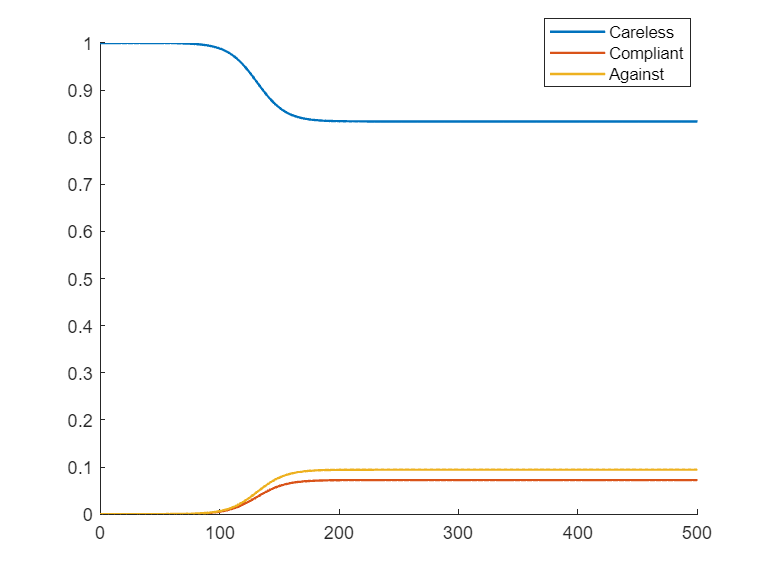

time = 500;
Co_zero = 100;
Ag_zero = 100;
[taxisRK2,xaxisRK2,yaxisRK2,zaxisRK2,awareness2] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,Co_zero, Ag_zero);
  
fig = fig+1;
figure(fig)
hold on
plot(taxisRK2,xaxisRK2, 'linewidth',1.3 )
plot(taxisRK2,yaxisRK2, 'linewidth',1.3 )
plot(taxisRK2,zaxisRK2, 'linewidth',1.3 )
legend('Careless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
hold off
legend("Position", [0.70777,0.8488,0.18929,0.11905])

Plot of the nullclines

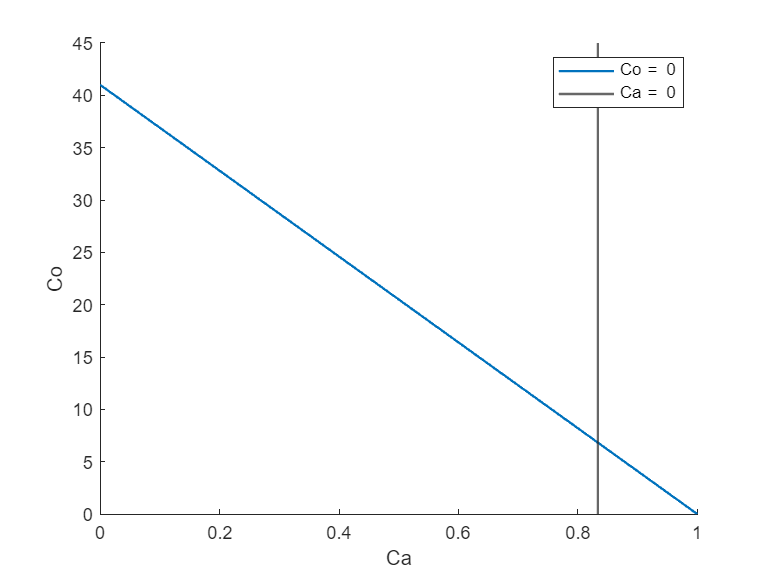

fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_1/k1), LineWidth= 1.3)
xlabel("Ca")
ylabel("Co")
legend('Co^ = 0', 'Ca^ = 0')
hold off

Definition of system equation and Jacobian calculation

syms Ca Co Ag

eq_Ca = -k1*Ca*Co - k2*(1-Ca-Co)*Ca + lambda_1*Co + lambda_2 * (1-Ca-Co);
eq_Co = +k1*Ca*Co - lambda_1*Co;

% The Jacobiana of this equation in this case is:
Jac(Ca, Co) = jacobian([eq_Ca, eq_Co], [Ca, Co])

$$Jac(Ca, Co) = \left(\begin{array}{cc} \mathrm{Ca}+\frac{\mathrm{Co}}{82}-\frac{11}{12} & \frac{\mathrm{Ca}}{82}-\frac{5}{492}\\ \frac{20\,\mathrm{Co}}{41} & \frac{20\,\mathrm{Ca}}{41}-\frac{50}{123} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(Ca,Co) = trace(Jac(Ca,Co))

$$Trac(Ca, Co) = \frac{61\,\mathrm{Ca}}{41}+\frac{\mathrm{Co}}{82}-\frac{217}{164}$$

% Determinant
d(Ca,Co) = det(Jac)

$$d(Ca, Co) = \frac{20\,{\mathrm{Ca}}^{2}}{41}-\frac{35\,\mathrm{Ca}}{41}+\frac{275}{738}$$

Substituing the equilibrium value in the trace and determinat to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this particular case the value of the Careless can be calculated with two different formula: Ca = $\lambda_1/k1$ or Ca = $\lambda_2/k2$

There is not an expression to find the value of the Compliant and Against compartment. It depends on the initial condition, the value of Co(0) and Ag(0) at the beginning of the simulation. Also, the trace depends on both the unkowns Ca and Co, while the determinant is a function of Ca only, but at the equilibrium is value is zero. In this case anything can be said about the stability of the equilibrium. 

value1 = lambda_1/k1; 
value2 =  (1-lambda_1/k1);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{10}{123}$$


det_J =  d(value1, value2)

$$det\_J = 0$$

## Caso R2 > R1 and R2 > 1

% Simulation parameters
R1 = 1.2;
R2 = 1.9;
k1 =  1/4; %from Ca to Co 
k2 = 1/5; %from C to Ag
lambda_1 = k1/R1; %fatigue to mantain Co behaviour
lambda_2 = k2/R2; %fatigue to mantain Ag behaviour

Simulation and printing the result with this   condition. 

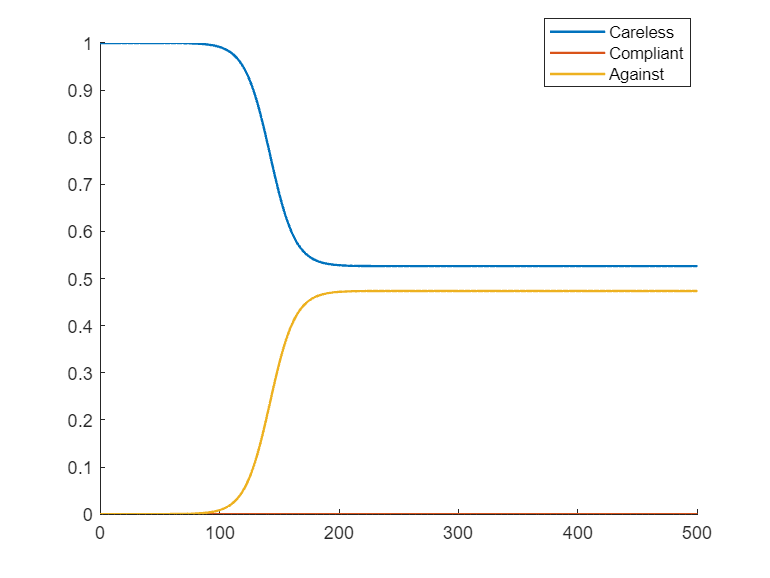

time = 500;
Co_zero = 40;
Ag_zero = 40;
[taxisRK,xaxisRK,yaxisRK,zaxisRK,awareness] = obj.Behaviour_RK_ic(k1,k2,lambda_1,lambda_2,time,Co_zero, Ag_zero);

fig = fig+1;
figure(fig)
hold on
plot(taxisRK,xaxisRK, 'linewidth',1.3 )
plot(taxisRK,yaxisRK, 'linewidth',1.3 )
plot(taxisRK,zaxisRK, 'linewidth',1.3 )
legend('Careless', 'Compliant', 'Against')
xlim([0 500])
ylim([0.000 1.000])
legend("Position", [0.70777,0.8488,0.18929,0.11905])
hold off

Plot of the nullclines

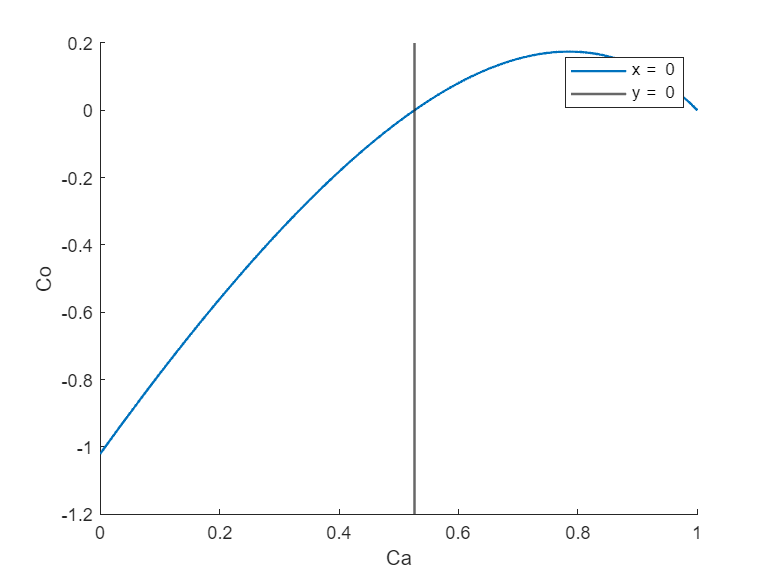

fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline(x,k1,k2,lambda_1,lambda_2), LineWidth=1.3)
xline((lambda_2/k2), LineWidth= 1.3)
xlabel("Ca")
ylabel("Co")
legend('x^ = 0', 'y^ = 0')
hold off

Another nullcline plot is here showed. It is the one obtained solving a different system of equation, the Careless/Against ones. Its shape in this case corresponds to the one visible in the case R1 >R2 and R1 >1.

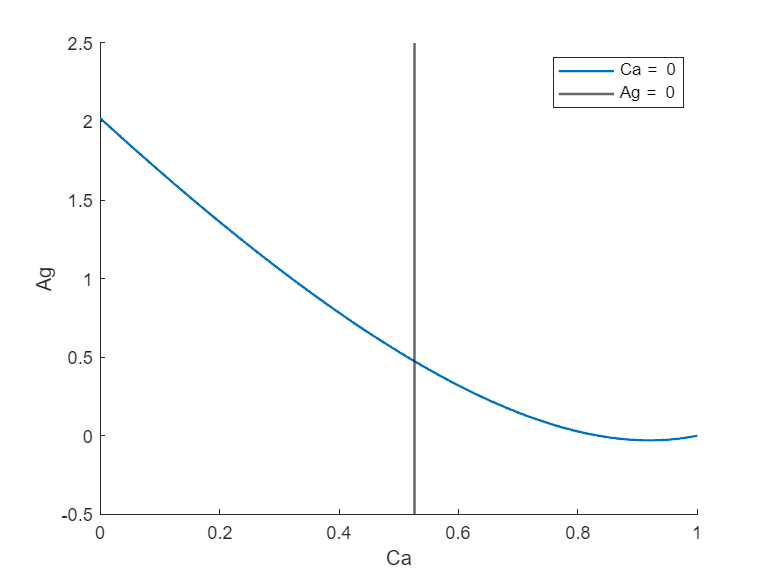

fig = fig+1;
figure(fig)
hold on
plot(x,y_nullcline(x, k1,k2,lambda_1, lambda_2), LineWidth=1.3)
xline((lambda_2/k2), LineWidth= 1.3)
xlabel("Ca")
ylabel("Ag")
legend('Ca^ = 0', 'Ag^ = 0')
hold off

Another possible nullcline plot. In this case the one obtained solving the system Complaint-Against. In this case the nullclines are two parallel lines. The one that is above represent the "dominant" groupm because has the large reproduction rate.  The only possible stable equilibrium in this case is the one corresponding to the point of the second nullcline in which Co = 0. 

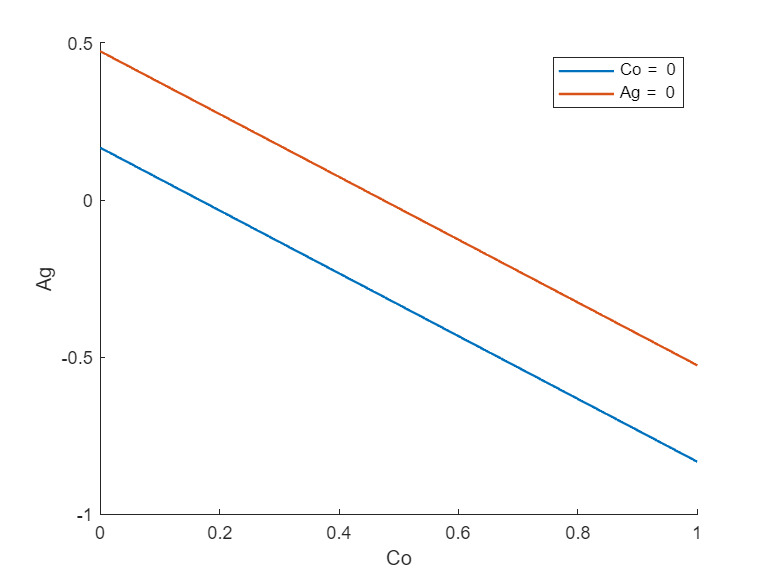

fig = fig+1;
figure(fig)
hold on
plot(x,x_nullcline2(x, k1,k2,lambda_1, lambda_2), LineWidth=1.3)
plot(x,y_nullcline2(x, k1,k2,lambda_1, lambda_2), LineWidth=1.3)
xlabel("Co")
ylabel("Ag")
legend('Co^ = 0', 'Ag^ = 0')
hold off

Definition of system equation and Jacobian calculation

syms Ca Co Ag

eq_Ca = -k1*Ca*(1-Ca-Ag) - k2*Ag*Ca + lambda_1*(1-Ca-Ag) + lambda_2 * Ag;
eq_Co = +k1*Ca*Co - lambda_1*Co;
eq_Ag = +k2*Ca*Ag - lambda_2*Ag;

% The Jacobiana of this equation in this case is:
Jac(Ca, Ag) = jacobian([eq_Ca, eq_Ag], [Ca, Ag])

$$Jac(Ca, Ag) = \left(\begin{array}{cc} \frac{\mathrm{Ag}}{20}+\frac{\mathrm{Ca}}{2}-\frac{11}{24} & \frac{\mathrm{Ca}}{20}-\frac{47}{456}\\ \frac{\mathrm{Ag}}{5} & \frac{\mathrm{Ca}}{5}-\frac{2}{19} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(Ca,Ag) = trace(Jac(Ca,Ag))

$$Trac(Ca, Ag) = \frac{\mathrm{Ag}}{20}+\frac{7\,\mathrm{Ca}}{10}-\frac{257}{456}$$

% Determinant
d(Ca,Ag) = det(Jac)

$$d(Ca, Ag) = \frac{{\mathrm{Ca}}^{2}}{10}-\frac{329\,\mathrm{Ca}}{2280}+\frac{7\,\mathrm{Ag}}{456}+\frac{11}{228}$$

Substituting the equilibrium value in the trace and determinant to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

The value at equilibrium in this case can be found using the formula Ca = $\lambda_1 / k1$ and Co = 1-$\lambda_1 / k1$   

value1 = lambda_2/k2; 
value2 =  (1-lambda_2/k2);
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{391}{2280}$$


det_J =  d(value1, value2)

$$det\_J = \frac{21}{2888}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable.

## Sensitivity analysis

Now are plotted some results obtained from the simulations of the behavioural model

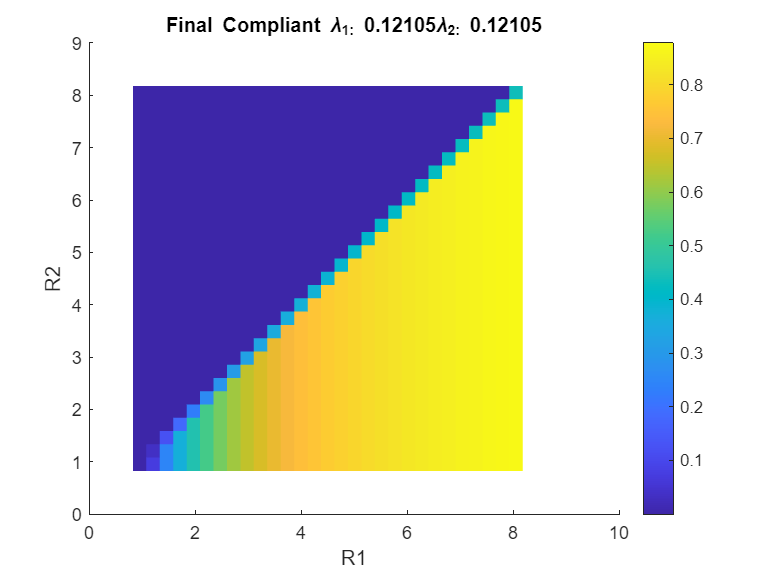

 load("data/multilpiBehaviour.mat")
 k1_vec = linspace(0.1, 0.99,30);
lam1_vec = linspace(1/5, 1/30, 20);
vec_R2 = [2,5,8,12,16,19]; % six values to calculated R2

%% Equilibrium plot of R1 and R2
fig = fig+1;
figure(fig)
%1,1
d1 = 10; d2 = 10;
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Co(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final Compliant "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

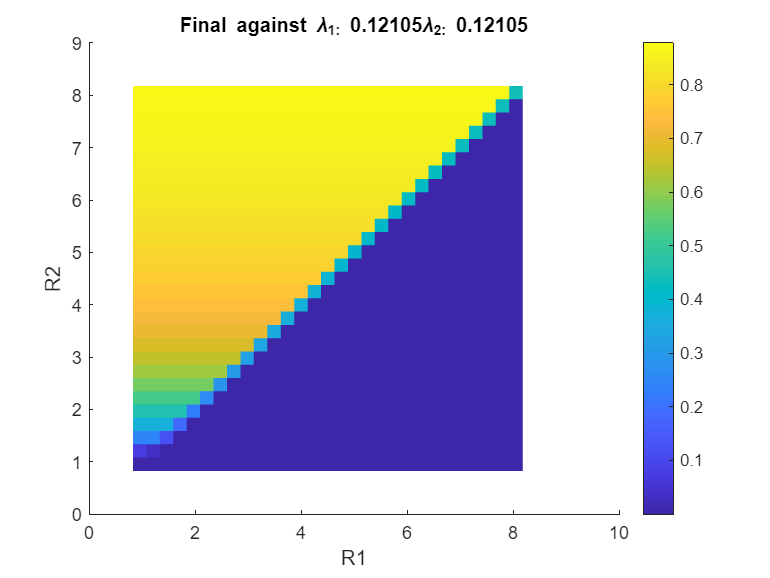

% 1,2
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Ag(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final against "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

These first two plots are the final value at equilibrium of Compliant and Against compartments. The Careless one is in the next figure.

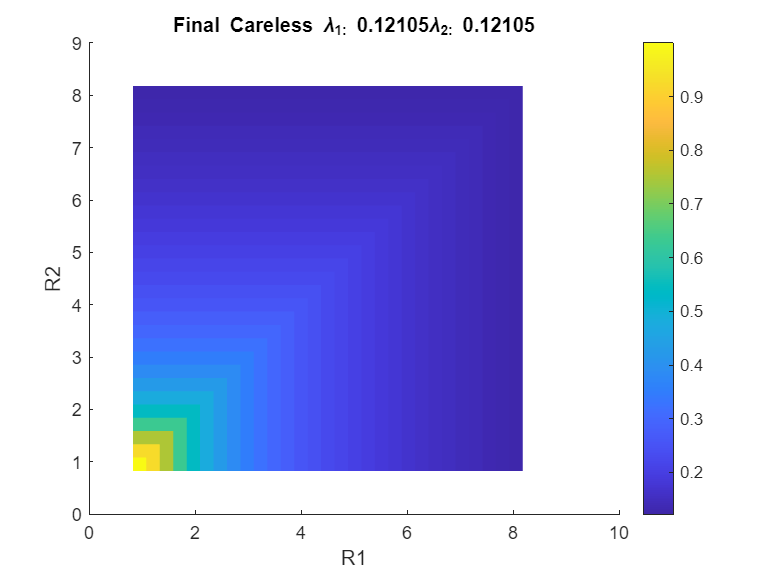

% Careless at equilibrium
fig = fig+1;
figure(fig)
r1 = k1_vec./lam1_vec(d1);
r2 = k1_vec./lam1_vec(d2);
[xx, yy] = meshgrid(r1,r2);
aga = reshape(final_Ca(:,:,d1,d2),30,30,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "Final Careless "+ '\lambda_1: '+ num2str(lam1_vec(d1)) +'\lambda_2: '+ num2str(lam1_vec(d2));
title(txt3)
xlabel('R1') 
ylabel('R2') 

The final plots are done to show the final system values as a variation of R1 parameter only.

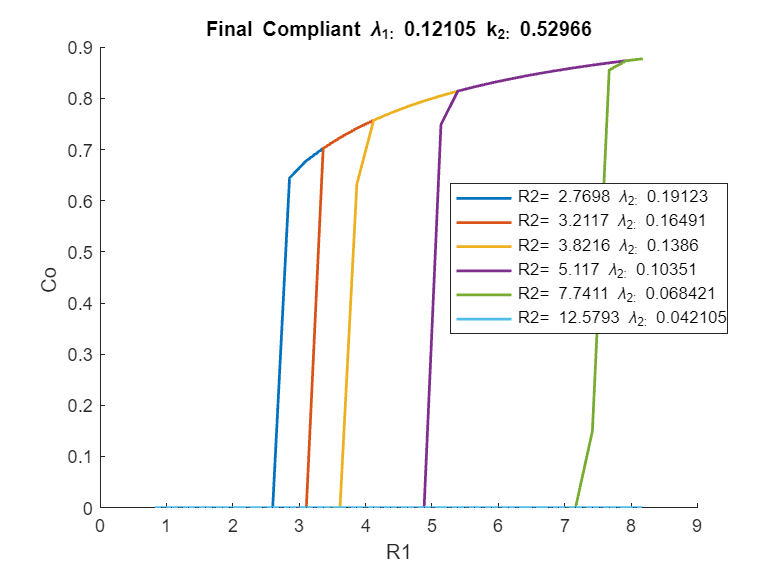

%% Equilibrium value function of R1
fig = fig+1;
figure(fig)
%1,1
d1 = 10; d3 = 15;
nexttile
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Co(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
legend("Position", [0.58547,0.42327,0.35893,0.25833])
txt3 = "Final Compliant "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel("Co ") 
hold off

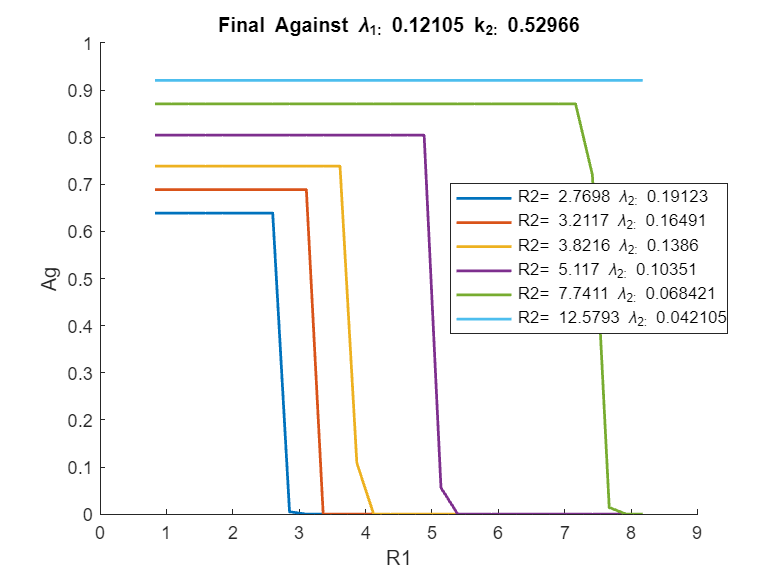

% 1,2
fig = fig+1;
figure(fig)
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Ag(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
legend("Position", [0.58547,0.42327,0.35893,0.25833])
txt3 = "Final Against "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel('Ag') 
hold off

nexttile(2)

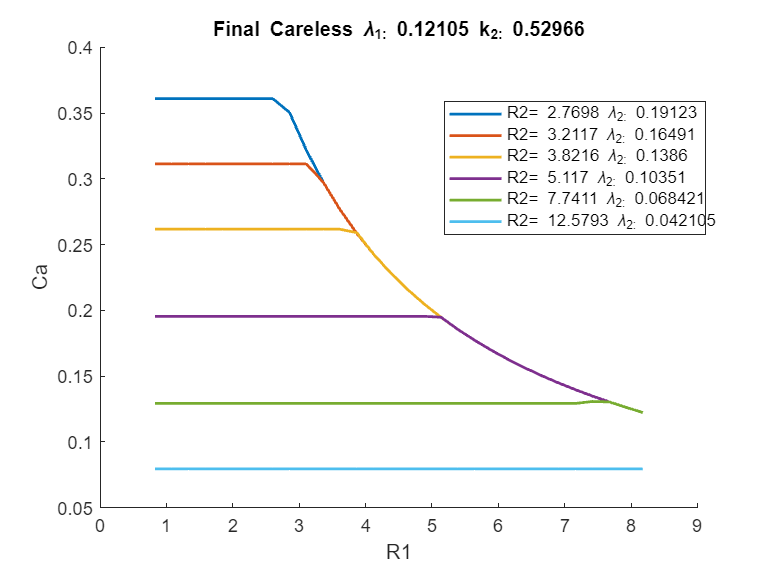

legend("Position", [0.87913,0.59867,0.33929,0.22976])
% 1,3
fig = fig+1;
figure(fig)
hold on
r1 = k1_vec./lam1_vec(d1);
for i = 1:6
    d2 = vec_R2(i);
    aga = reshape(final_Ca(:,d3,d1,d2),1,30,[]);
    zz = aga; %zz = transpose(zz);
    txt =  "R2= "+ num2str(k1_vec(d3) /lam1_vec(vec_R2(i)))+ ' \lambda_2: '+ num2str(lam1_vec(d2));
    plot(r1,zz,'LineWidth',1.5 ,'DisplayName',txt)
end
legend show
txt3 = "Final Careless "+ "\lambda_1: "+ num2str(lam1_vec(d1)) +" k_2: "+ num2str(k1_vec(d3));
title(txt3)
xlabel('R1') 
ylabel('Ca') 
hold off

legend("Position", [0.57653,0.59521,0.33929,0.22976])

## Function section

function y = x_nullcline(x, k1,k2,lambda_1, lambda_2)
y = (x.*(k2-k2*x+lambda_2)-lambda_2)./(x.*(k2-k1)+(lambda_1-lambda_2));
end

function y = y_nullcline(Ca, k1,k2,lambda_1, lambda_2)
y = (Ca.*(k1-k1*Ca+lambda_1)-lambda_1)./(Ca.*(k1-k2)-lambda_1+lambda_2);
end

function y = x_nullcline2(x, k1,k2,lambda_1, lambda_2)
    R1 = k1/lambda_1; 
    y = -x - 1/R1 +1;
end

function y = y_nullcline2(x, k1,k2,lambda_1, lambda_2)
    R2 = k2/lambda_2;
    y = -x - 1/R2 +1;
end